fs=48000;
f0=18000;

mode='s7/';
fileFolder = fullfile(['receive/', mode]);
dirOutput = dir(fullfile(fileFolder,'*.pcm'));
fileNames = {dirOutput.name};
file_name = fileNames{end}

file_name = 'google9record1641783830279.pcm'

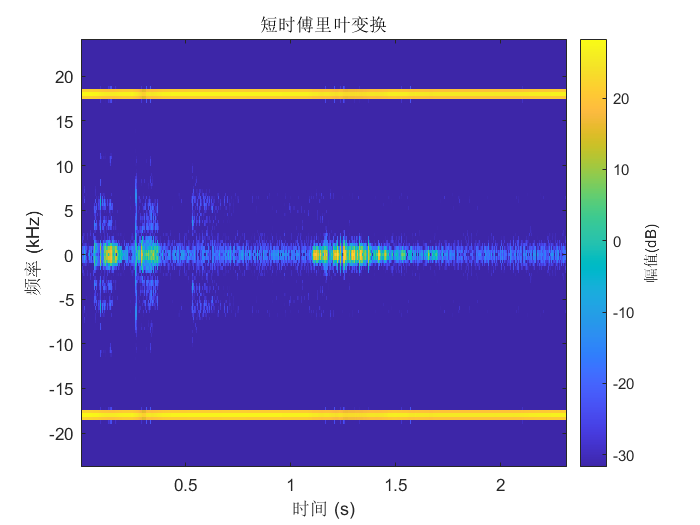



file=['receive/' , mode, file_name];

data= importdata(file);
data=audioread("1-1.wav");
data=data(24000:end);
stft(data,fs)

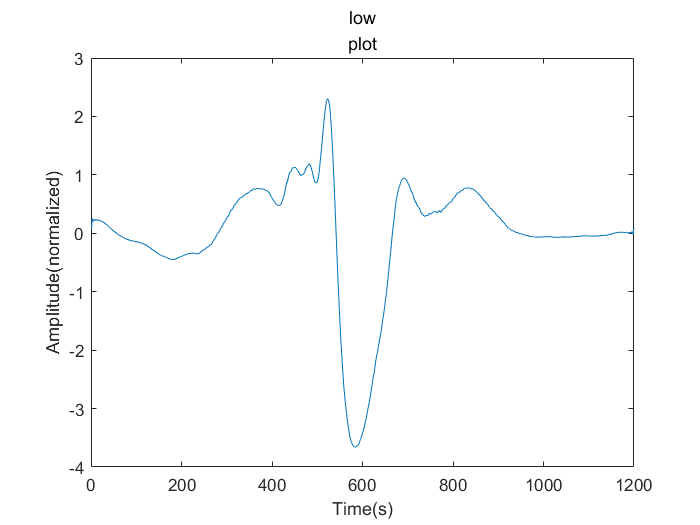

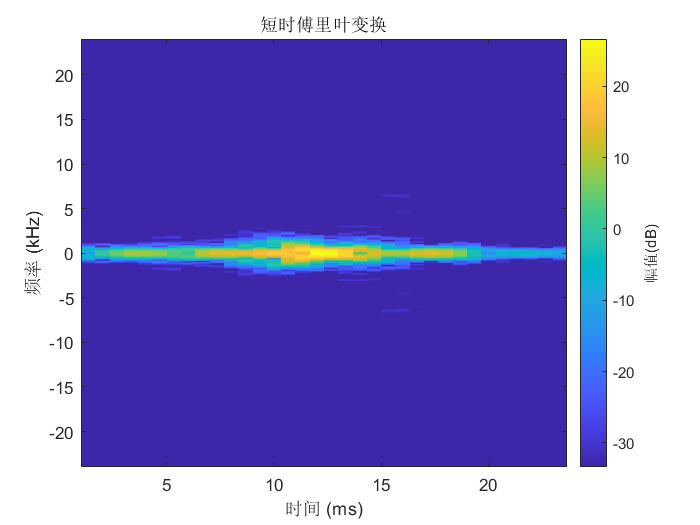

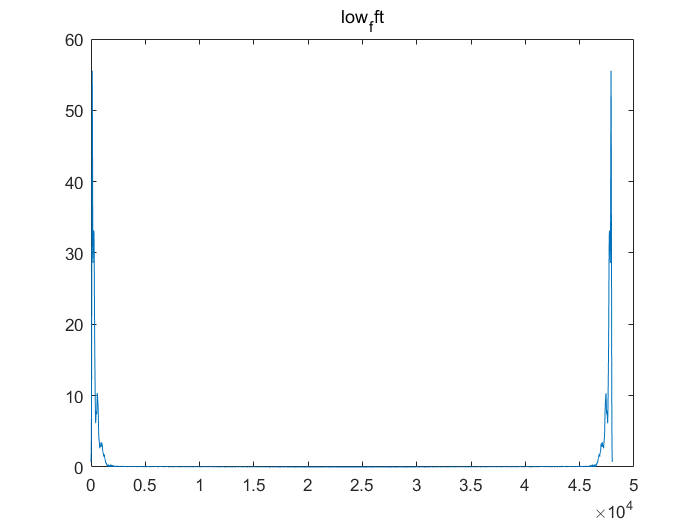

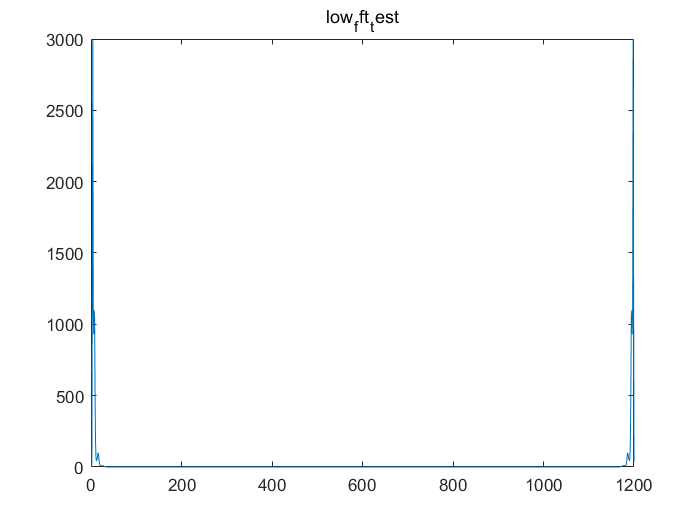

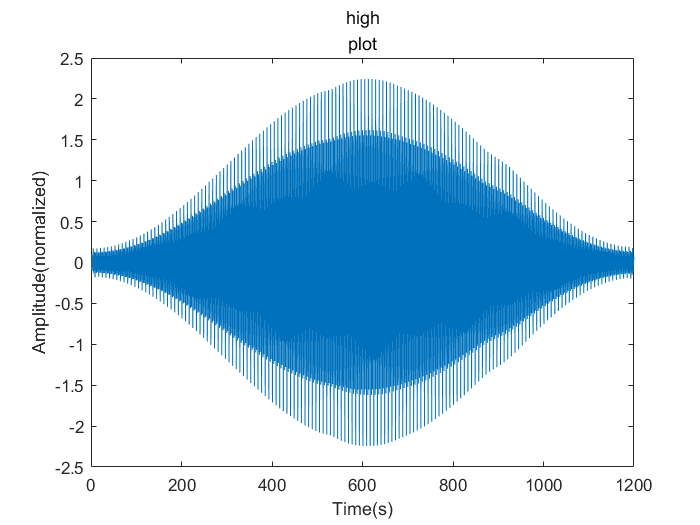

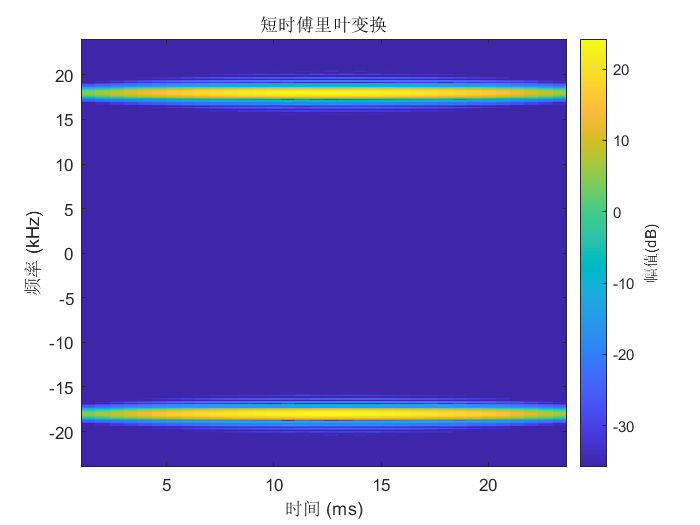

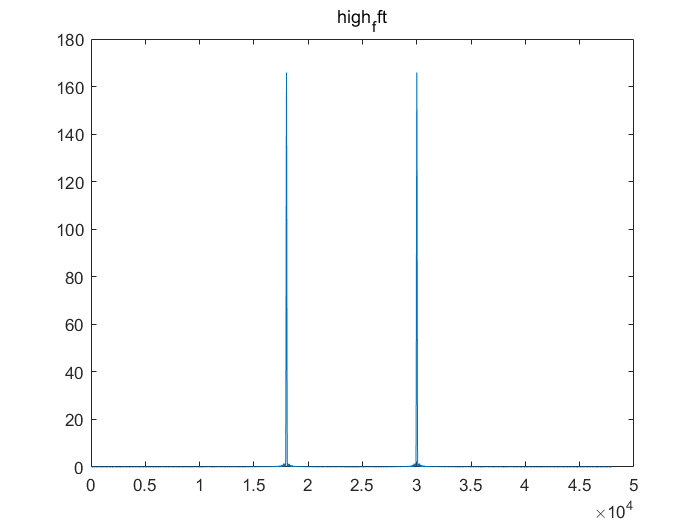

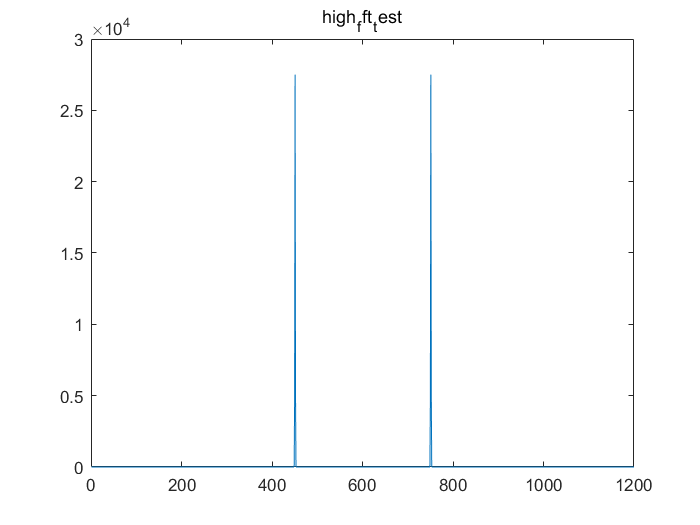


% 
% window=512;%滑动窗大小
% noverlap=256;%重叠样本数为100重叠99平移样本,每隔1个单位画一个框计算
% nfft=2048;
% spec_data=spectrogram(data, window, noverlap,nfft, fs, 'yaxis');  
% spec_data=abs(spec_data).*abs(spec_data);%取模
% spec_data=10*log10(spec_data);%取对数
% dim2freq=linspace(0,fs/2,size(spec_data,1));
% xlabels=0:1:size(spec_data,2);
% imagesc(xlabels,dim2freq,spec_data);%绘制语谱图
% colorbar();%显示colorbar()
% axis xy;%颠倒顺序
% hold on

% wlen=1024
% inc=512
% [f0,idx] = pitch(data,fs, 'WindowLength',wlen,'OverlapLength',inc);%求取语音的基音频率
% fn1=size(f0,1);
% result_f0=f0(find(f0<400));%筛选符合条件的基音频率
% figure()
% plot(result_f0);%绘制基音频率
% title('基音频率f0')
% xlabel('帧')
% ylabel('频率/Hz')
% axis([0 fn1 0 400])%设置坐标轴范围
% power_am=getpower(data);
% figure;
% plot(power_am)




% getIQ(data);
% 
% high_data=highpass(data, 10000, fs);
% stft(data, fs, 'FFTLength', 1024);

% low_data=lowpass(data, 8000, fs)
% 
% 
% write_data=int16(data);
% % write_data=int16(low_data);
% audiowrite("test.wav", write_data, fs);
% test_data=importdata("test.wav").data;
% sound(test_data, 48000, 16);
% 
% data=test_data
% 
% 
data=plot_highpass(data, fs);

% 
% 
% analysis_single(data, fs, f0);
% 
% 




